ans = 2×2 table
    Label     Count
    ______    _____

    neg_64    2436 
    pos       2416 


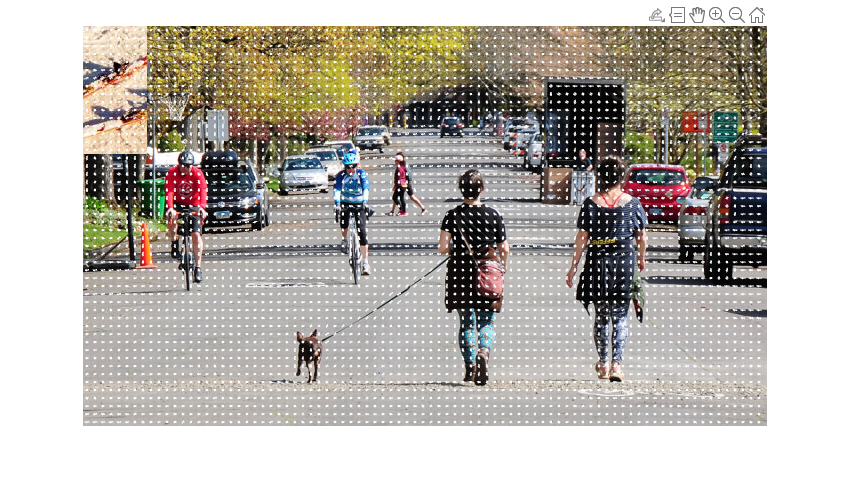

images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)

figure;

Index exceeds the number of array elements. Index must not exceed 4852.

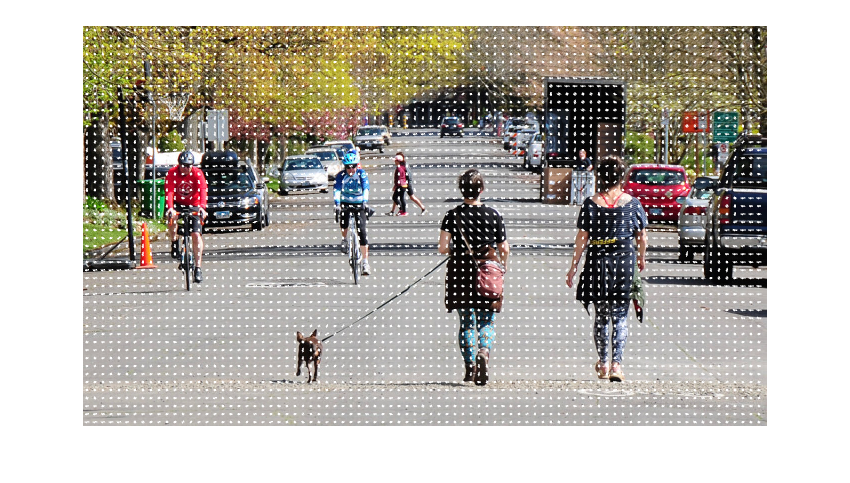

It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

% Przygotowanie danych treningowych
%X_train = zeros(length(images.Files), 3780);
X_train = zeros(length(images.Files), 3780);
Y_train = images.Labels;

for i=1:length(images.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images.Files{i});
        fprintf("Error: %s", ME);
    end
end

Extracting HOG features i=500...
Extracting HOG features i=1000...
Extracting HOG features i=1500...
Extracting HOG features i=2000...
Extracting HOG features i=2500...
Extracting HOG features i=3000...
Extracting HOG features i=3500...
Extracting HOG features i=4000...
Extracting HOG features i=4500...


% Wytrenowanie klasyfikatora SVM
C = 10;
gamma = 0.1;

images.Labels(1)

ans = categorical
     neg_64 



img_classes = {'pos', 'neg_64'};

t = templateSVM('KernelFunction','gaussian','BoxConstraint', C, 'KernelScale',gamma);
model   = fitcecoc(X_train, Y_train, 'Learners', t, 'ClassNames', img_classes);




% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 8;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 60;

dets = [];
scores = [];
labels = {};

for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        pred = model.predict(sub_hog);
        out(j+1, i+1) = strcmp(pred, 'pos');
    end
end

best_score = min(min(out))

figure;
imagesc(out)
figure;
mins = imregionalmin(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;
    
    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

scale = 1

count_x = 77

count_y = 34

Error using type
Too many output arguments.

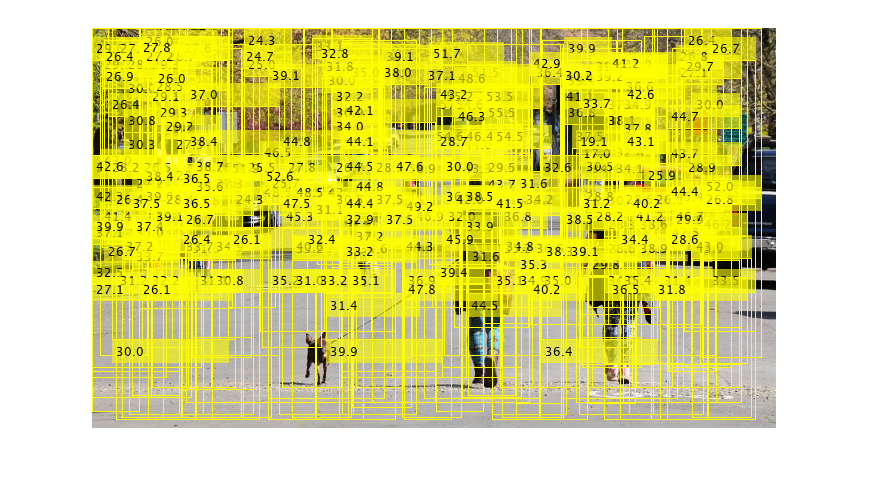

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

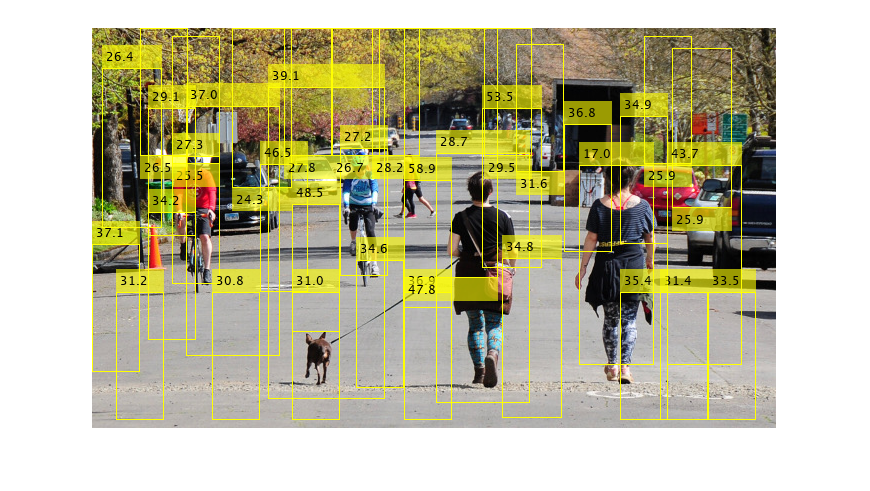

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

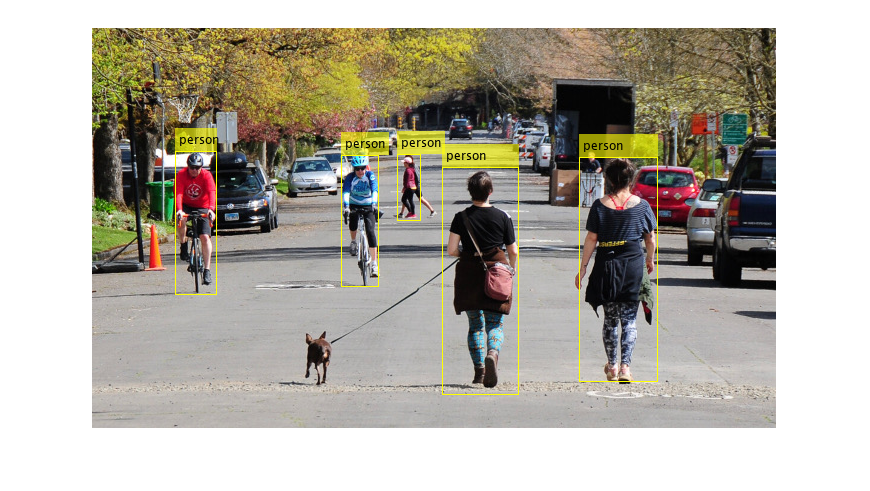

gt_rect=gTruth.LabelData.person{1,1};
ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);

score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)

ratio =          0         0    0.0469         0         0         0    0.0054         0         0    0.7887         0         0         0    0.1715         0
         0         0         0         0         0         0         0    0.0034    0.7007         0         0    0.0006         0         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.0060         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.7491         0         0
    0.8439         0         0    0.0041         0         0         0         0         0         0         0         0         0         0         0


[best_overlaps, good_ids] = max(ratio, [], 2)

best_overlaps =     0.7887
    0.7007
    0.0060
    0.7491
    0.8439


good_ids =     10
     9
    12
    13
     1


iou = 0.4;
best_ids = good_ids(best_overlaps > iou)

best_ids =     10
     9
    13
     1


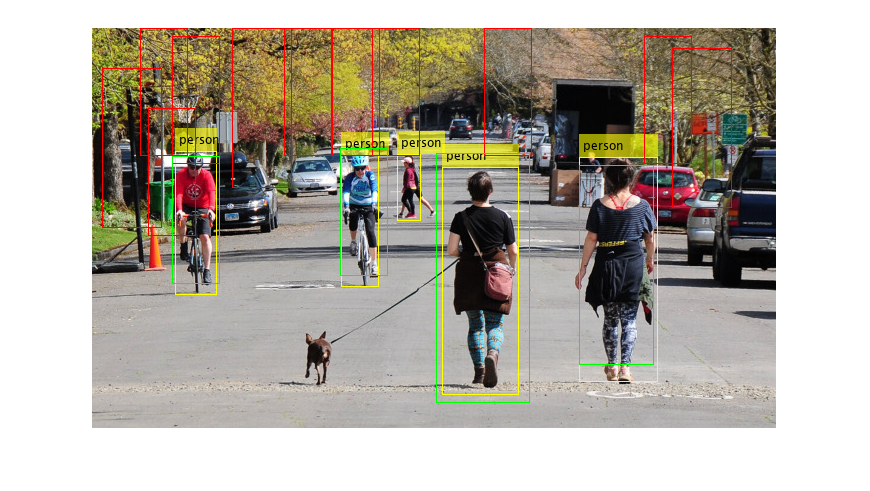

pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

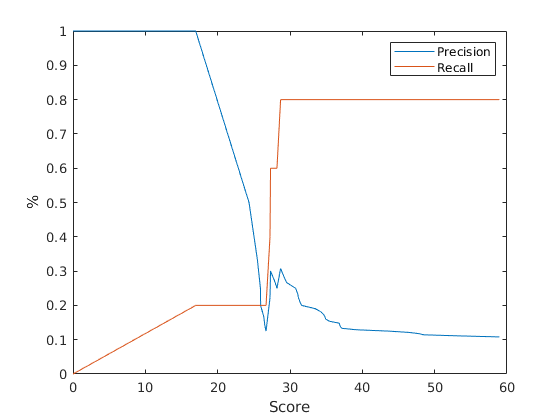

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");

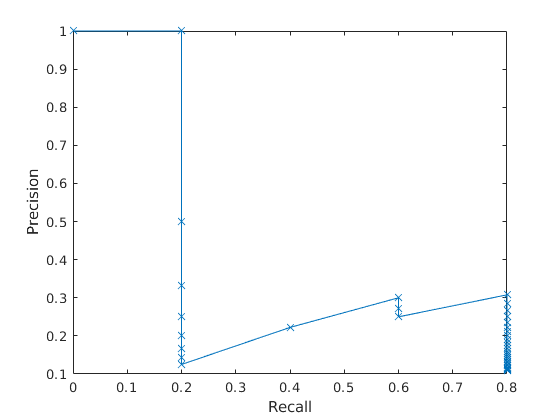

figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");

ap = trapz(R, P)

ap = 0.3427

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end